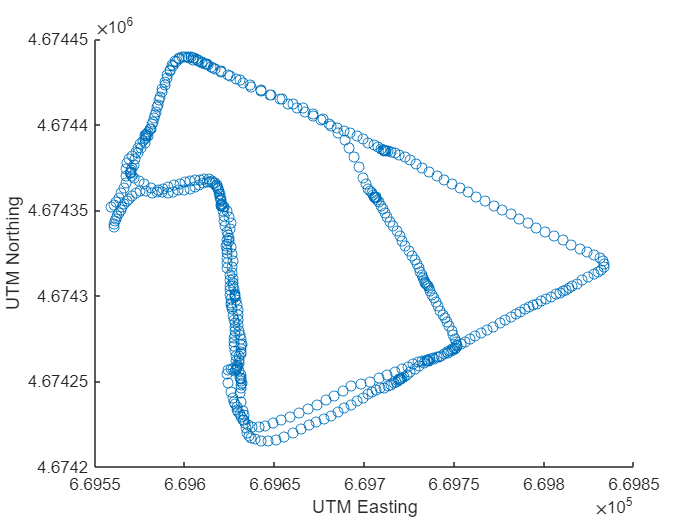

addpath("D:\Documents\bags");

%Extracting data from rosbag
bag =  rosbag("reading2.bag");

gps_bag = select(bag, 'Topic', '/pub_gps_data');
msgs = readMessages(gps_bag,"DataFormat","struct");

xPoints = cellfun(@(m) double(m.UtmEast),msgs);
yPoints = cellfun(@(m) double(m.UtmNorth),msgs);

% UTM Northing vs UTM Easting plot
scatter(xPoints,yPoints)
ax = gca;
ax.XAxis.Exponent = 5;
ax.YAxis.Exponent = 6;
xlabel("UTM Easting");
ylabel("UTM Northing");